# Solar Data Extraction

This script is designed to facilitate the extraction of solar energy data from available plant data contained in GRIP reports. The script asks that end users define up to four variables. First, the month should be selected from the available list. Then, users are asked to zoom in on the days of interest that they would like to extract. By default, this script selects the first week of every month from midnight on the starting day to 23:59 of the ending day. 

*To generate a single day of data, toggle the avaialble option. *

## Step 1: Extract Monthly Power Data


% Section 1: Select month and get specific data from grip reports.

% this returns the full path to the current file (function or script)
fullFileName = matlab.desktop.editor.getActiveFilename;

% split off the folder
[folderPath, ~, ~] = fileparts(fullFileName);
[path,~,~] = fileparts(folderPath);

%add complete folder & subfolders to cd
cd(path)
addpath(genpath(path));

%Initialize Loop and Final object
dataFolder = fullfile(path, '_data');

if ~isfolder(dataFolder)
    error('Folder "_data" not found or not on path. Please ensure that the folder exists at: %s', filePath);
else
    disp("Folder found")
    warning("off", "MATLAB:table:ModifiedAndSavedVarnames")
end

Folder found



%dictionary for pulling power reports
month2num = containers.Map({'JAN'
    'FEB'
    'MARCH'
    'APRIL'
    'MAY'
    'JUNE'
    'JULY'
    'AUGUST'
    'SEPTEMBER'
    'OCTOBER'
    'NOVEMBER'
    'DECEMBER'}, cellstr(num2str((1:12)','%02d')));

month2days = containers.Map({'JAN'
    'FEB'
    'MARCH'
    'APRIL'
    'MAY'
    'JUNE'
    'JULY'
    'AUGUST'
    'SEPTEMBER'
    'OCTOBER'
    'NOVEMBER'
    'DECEMBER'}, {30,28,31,30,31,30,31,31,30,31,30,31});
%Step 1.1: User Input
month = "MAY";

%Step 1.2: Import dataset
% Get the list of files matching the pattern
filePattern = fullfile(dataFolder, '21?? GRIP*.xlsx');
files = dir(filePattern); %used for selecting files

%select file that matches the desired month
fileIdx = contains(string({files.name}), "21" + num2str(month2num(month), '%02d'));
matchFile = files(fileIdx);
filename = matchFile.name;
fprintf("Reading File: %s\n", filename)

Reading File: 2105 GRIP POWER REPORT Rev1.xlsx


% Import Column C for rows 14 to 44653 (DateTime)
dateTime = readtable(filename, 'Sheet', 'RawKW','Range', 'C13:C44653','VariableNamingRule', 'modify');
disp("...")

...


% Import columns AW to AZ for rows 14 to 44653
pwrDemand = readtable(filename, 'Sheet', 'RawKW','Range', 'CI13:CI44653','VariableNamingRule', 'modify');
disp("...")

...


pwrAdmin = readtable(filename,'Sheet','RawKW','Range','DB13:DB44653','VariableNamingRule', 'modify');
disp("...")

...



pwrSolar = readtable(filename, 'Sheet', 'RawKW','Range', 'CO13:CO44653','VariableNamingRule', 'modify');

if iscell(pwrSolar.GRIP_9043_JI_0001_PowerNetInstant)
    disp(filename + " Contains erroneous data")
    pwrSolar.GRIP_9043_JI_0001_PowerNetInstant = cellfun(@(x) str2double(x), pwrSolar.GRIP_9043_JI_0001_PowerNetInstant);
end

% Combine the two parts horizontally
solarData = table2timetable(rmmissing([dateTime, pwrDemand, pwrSolar,pwrAdmin]));

%Step 1.3: Plot data.
figure;
plot(solarData,"DateTime","GRIP_9043_JI_0001_PowerNetInstant", LineStyle="none",Marker=".")
hold on

%build x axis
ax = gca;
ax.XTick = dateshift(min(solarData.DateTime),'start','day'):caldays(1):...
    dateshift(max(solarData.DateTime),'start','day');
ax.XGrid = 'on';
hold off

## Step 2: Select days of interest.

Note: Some months do not have a full dataset. If there is some data missing, it will not return an error, but it will not show in the final .xlsx file. If no data is available, you will be met with an error.

See the plot below to identify any gaps in data.  Small gaps in between data are filled using linear interpolation. 

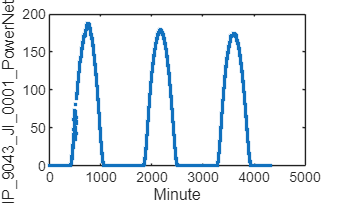

if exist("month", "var")
    day_options = 1:month2days(month);

    start_day = day_options(20);
    end_day = start_day; %fallback logic.
    default_file_name = "SolarData_2021_"+ num2str(month2num(month))+"_"+start_day;

    end_day_options = day_options(day_options>=start_day);
    end_day = end_day_options(3);
else
    disp("Please select an appropriate month.")
end

%Step 4.2: Finalize Dates
startdate = datetime("2021-" + month2num(month)+"-"+num2str(start_day));
enddate = datetime("2021-" + month2num(month)+"-"+num2str(end_day));


t0 = dateshift(startdate,'start','day');
t1 = dateshift(enddate,'end','day'); %if simming more than one day

tr = timerange(t0, t1);
if height(solarData(tr, :)) == 0
    error('No data available in solarData2021 between t0 and t1.');
end

%fill gaps with linear interpolation
simRange = fillmissing(solarData(tr,:),'linear');

%generate final table
simRange_table = rmmissing(timetable2table(simRange));

minsSinceStart = minutes(simRange_table.DateTime - simRange_table.DateTime(1));

simRange_table.Minute = minsSinceStart+1;           % attach new column
simRange_table = movevars(simRange_table, ...       % move Minute to col 1
    'Minute', 'Before', 1);

%plo
figure;
plot(simRange_table,"Minute","GRIP_9043_JI_0001_PowerNetInstant", LineStyle="none",Marker=".")

## Step 3: Save.

Note: The output file always returns a .xlsx file. 

Please define the output folder and output file names.

outputFolder_str = string(fullfile(path,"SolarSimulationData"));
saveFolder = "C:\Users\joshl\Desktop\ARC_Complete\SolarSimulationData";
saveFile = "SolarData_2021_02_20";
writeFileName = fullfile(saveFolder, saveFile + ".xlsx");
writetable(simRange_table(:,:),writeFileName,"WriteMode","overwrite");
fprintf("Saved %s.", writeFileName)

Saved C:\Users\joshl\Desktop\ARC_Complete\SolarSimulationData\SolarData_2021_02_20.xlsx.